# TRF_mkFigure4

Description

## computation (for Figure 4B)

% make stimulus
t   = 0:0.001:1;
s1  = double(t<1/60);
s2  = double(t<2/60);

% make impulse response function
tau = 0.100;
h   = t .* exp(-t/tau);
h   = double(h/sum(h));

% make linear prediction to 17ms and 33ms stimulus
r1.linear = convCut(s1, h, length(t));
r2.linear = convCut(s2, h, length(t));

% make CTS prediction
cts = @(x,s) x.^2./(s^2+x.^2);
sigma = [1, 0.01];

r1.ctsSigmaBig = [cts(r1.linear, sigma(1)); cts(r2.linear, sigma(1))];
r1.ctsSigmaSml = [cts(r1.linear, sigma(2)); cts(r2.linear, sigma(2))];


## plot Figure 4B

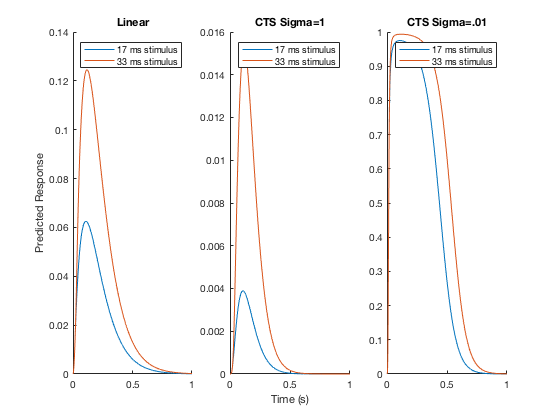

figure (4), clf
set(gcf, 'Color', 'w');
subplot(1,3,1)
plot(t, r1.linear, t, r2.linear)
title('Linear')
ylabel('Predicted Response')
legend('17 ms stimulus', '33 ms stimulus'), box off

subplot(1,3,2)
plot(t, r1.ctsSigmaBig(1, :),t, r1.ctsSigmaBig(2, :))
title('CTS Sigma=1'), xlabel('Time (s)')
legend('17 ms stimulus', '33 ms stimulus'), box off

subplot(1,3,3)
plot(t, r1.ctsSigmaSml(1, :), t,r1.ctsSigmaSml(2, :))
title('CTS Sigma=.01')

legend('17 ms stimulus', '33 ms stimulus'), box off